clear all;
cover = readtable('covtype.csv'); %%581012 observations
%%turn into matrix 
%%randomly select 20k obs
rand_index = randi(581012,20000,1); 
covermat = cover{:,:}(rand_index,:);
varNames = cover.Properties.VariableNames;
%%get labels
target = covermat(:,55);
%%numerical features
cov_numerical = covermat(:,1:10);
%%mean 0, sd 1
cov_normal = normalize(cov_numerical);
%%unique identities
uniqueTarget = unique(target);

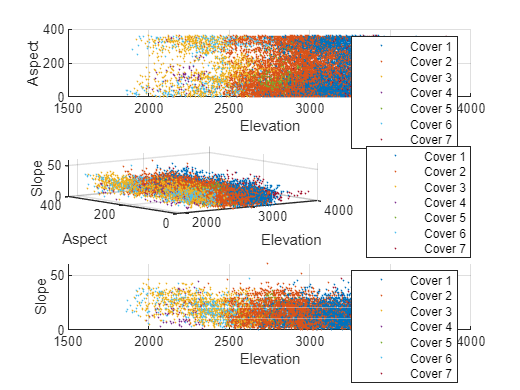

%%aspect, slope, and elevation separate the classes pretty well 
colors = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840]};
% Initialize some axes
elevation = cov_numerical(:,1);
aspect = cov_numerical(:,2);
slope = cov_numerical(:,3);
figure(2)
subplot(3,1,1)
view(2)
xlabel('Elevation'); ylabel('Aspect'); zlabel('Slope');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(elevation(ind),aspect(ind),slope(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,2)

view(3)
xlabel('Elevation'); ylabel('Aspect'); zlabel('Slope');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(elevation(ind),aspect(ind),slope(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      hold on;
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,3)
view(2)
xlabel('Elevation'); ylabel('Slope'); zlabel('Aspect');
grid on
hold on

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(elevation(ind),slope(ind),aspect(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

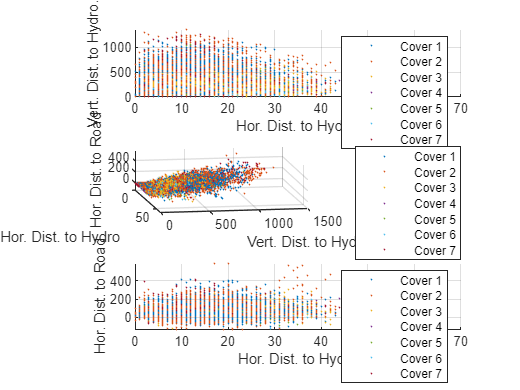

%Horizontal Distances and Vertical Distances

hordist1 = cov_numerical(:,3);
vdist = cov_numerical(:,4);
hordist2 = cov_numerical(:,5);

figure(3)
subplot(3,1,1)
view(2)
xlabel('Hor. Dist. to Hydro.'); ylabel('Vert. Dist. to Hydro.'); zlabel('Hor. Dist. to Road.');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hordist1(ind),vdist(ind),hordist2(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,2)

view(80,30)
xlabel('Hor. Dist. to Hydro'); ylabel('Vert. Dist. to Hydro'); zlabel('Hor. Dist. to Road');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hordist1(ind),vdist(ind),hordist2(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,3)
view(2)
xlabel('Hor. Dist. to Hydro'); ylabel('Hor. Dist. to Road'); zlabel('Vert. Dist. to Hydro');
grid on
hold on

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hordist1(ind),hordist2(ind),vdist(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

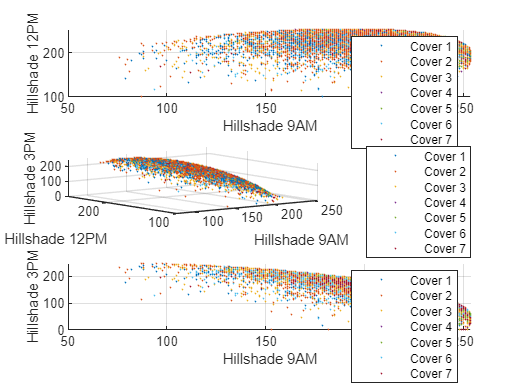

hillshade9 = cov_numerical(:,7);
hillshade12 = cov_numerical(:,8);
hillshade3 = cov_numerical(:,9);

figure(4)
subplot(3,1,1)
view(2)
xlabel('Hillshade 9AM'); ylabel('Hillshade 12PM'); zlabel('Hillshade 3PM');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hillshade9(ind),hillshade12(ind),hillshade3(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,2)

view(3)
xlabel('Hillshade 9AM'); ylabel('Hillshade 12PM'); zlabel('Hillshade 3PM');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hillshade9(ind),hillshade12(ind),hillshade3(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

subplot(3,1,3)
view(2)
xlabel('Hillshade 9AM'); ylabel('Hillshade 3PM'); zlabel('Vert. Dist. to Hydro');
grid on
hold on

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      plot3(hillshade9(ind),hillshade3(ind),hillshade9(ind),'.','color',cell2mat(colors(k)),'markersize',1); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

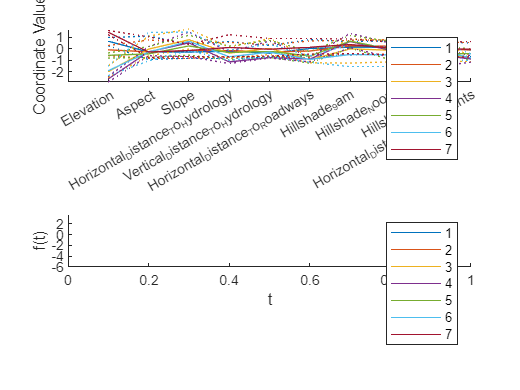

%%interesting plots

figure(5)
subplot(2,1,1)
parallelcoords(cov_numerical, 'group',target, 'standardize','on', 'labels',varNames(1:10),'quantile',.25)
subplot(2,1,2)
andrewsplot(cov_numerical, 'group',target, 'standardize','on', 'quantile', .25)

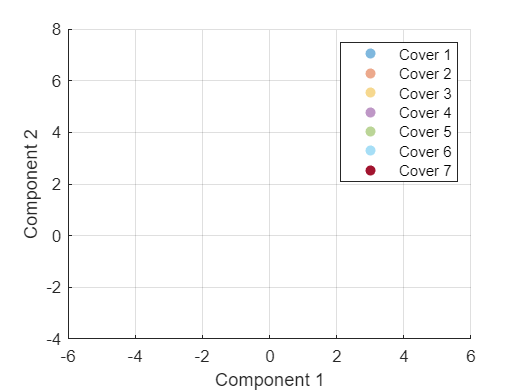

%%PCA
%% 25% first component, 21% second component, 17% third component, 10% fourth component, 22% rest of components 
[coeff,score,latent,tsquared,explained,mu] = pca(cov_normal); 

pca1 = score(:,1);
pca2 = score(:,2);
pca3 = score(:,3);

figure(6)

xlabel('Component 1'); ylabel('Component 2');
grid on
hold on 
for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k); 
      sz = 3;
      alpha(0.5)
      scatter(pca1(ind),pca2(ind), sz, cell2mat(colors(k)), 'filled'); 
      
end
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

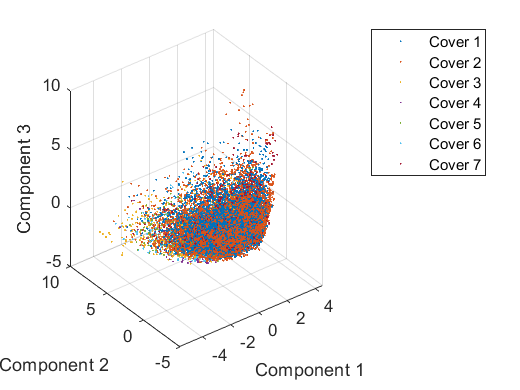


figure(7)
xlabel('Component 1'); ylabel('Component 2'); zlabel('Component 3');
grid on
hold on 
view(3)

for k = 1:length(uniqueTarget)
      ind = target ==uniqueTarget(k);
      alpha(0.5)
      plot3(pca1(ind),pca2(ind), pca3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',1); 
      
      
end
hold off
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

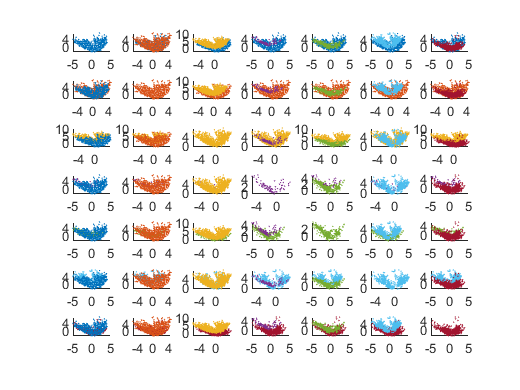


%%suggests data is not able to project well using PCA for all 7 covertypes, does it differentiate well for two at a time?

figure(8)
grid on
hold on

counter = 1;
for k = 1:(length(uniqueTarget))
    ind1 = target ==uniqueTarget(k);
    for j = 1:length(uniqueTarget)
      subplot(7,7,counter);
      ind2 = target == uniqueTarget(j);
      alpha(0.2)
      sz =1;
      scatter(pca1(ind1),pca2(ind1), sz, cell2mat(colors(k)), 'filled');
      hold on
      scatter(pca1(ind2), pca2(ind2), sz, cell2mat(colors(j)), 'filled')
      hold off
      counter = counter +1;
    end
      
end



%%graphs suggest data is non-linear

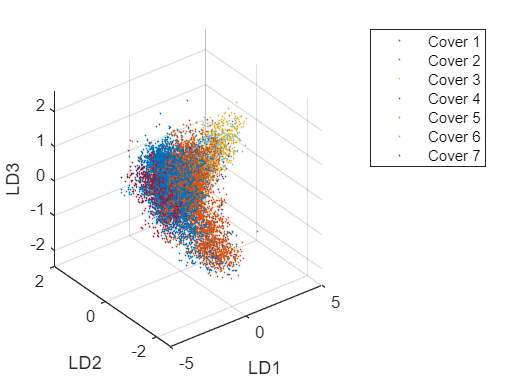

%%LDA 
within = cell(7, 1);
centroid_mat = [];
length_vec = [];
for k = 1:length(uniqueTarget)
    ind = target ==uniqueTarget(k); 
    mat = cov_normal(ind,:);
    length_vec(k) = size(mat,1);
    group_mean = sum(mat,1)/size(mat,1);
    centroid_mat(:,k) = group_mean;
    scatter_mat = (bsxfun(@minus,mat,group_mean))'*(bsxfun(@minus,mat,group_mean));
    within{k} = scatter_mat;
end

sw = within{1} + within{2} + within{3} + within{4} + within{5} + within{6} + within{7};
inv(sw); %%invertible
global_centroid = sum(cov_normal,1)/size(cov_normal,1);
dif_mat = centroid_mat - repmat(global_centroid,7,1)';
Mtild = (sqrt(length_vec).*dif_mat)';
sb = Mtild'*Mtild;
[V,D,W] = eig(sb,sw); %% V contains the projection directions
norms = sqrt(sum(V.^2,1));
V = bsxfun(@rdivide,V,norms); 
LDA_proj = cov_normal*V';

proj1 = LDA_proj(:,1);
proj2 = LDA_proj(:,2);
proj3 = LDA_proj(:,3);


figure(9)
xlabel('LD1'); ylabel('LD2'); zlabel('LD3');
grid on
hold on 
view(3)
for k = 1:length(uniqueTarget)
      ind = target == uniqueTarget(k); 
      plot3(proj1(ind),proj2(ind), proj3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',1); 
end
      
legend('Cover 1','Cover 2','Cover 3','Cover 4','Cover 5', 'Cover 6', 'Cover 7')

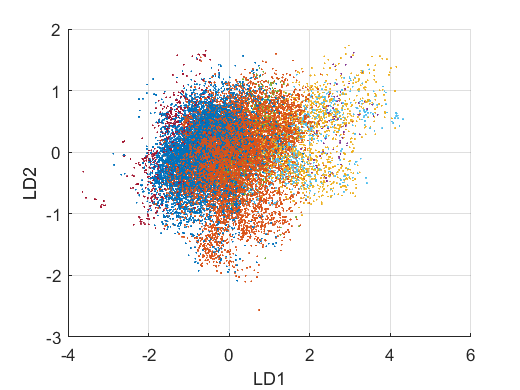



figure(10)
xlabel('LD1'); ylabel('LD2'); zlabel('LD3');
grid on
hold on 
view(2)
for k = 1:length(uniqueTarget)
      ind = target == uniqueTarget(k); 
      plot3(proj1(ind),proj2(ind), proj3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',1); 
end

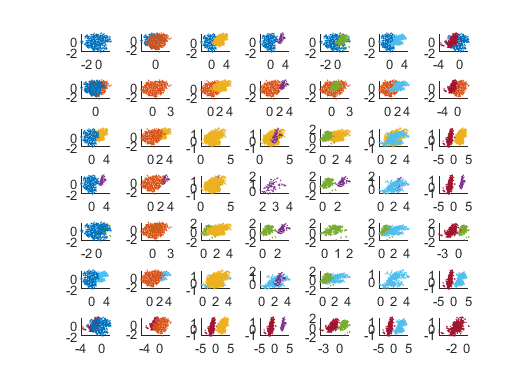


figure(11)
grid on
hold on

counter = 1;
for k = 1:(length(uniqueTarget))
    ind1 = target ==uniqueTarget(k);
    for j = 1:length(uniqueTarget)
      subplot(7,7,counter);
      ind2 = target == uniqueTarget(j);
      alpha(0.2)
      sz =1;
      scatter(proj1(ind1),proj2(ind1), sz, cell2mat(colors(k)), 'filled');
      hold on
      scatter(proj1(ind2), proj2(ind2), sz, cell2mat(colors(j)), 'filled')
      hold off
      counter = counter +1;
    end
      
end

%%we start to get good separation between classes

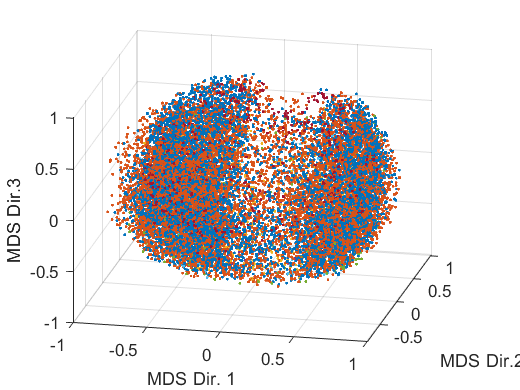

%%MDS 
D_mat = pdist(cov_normal,'cosine'); 
%%not necessarily looking for separation here
%%simply mapping them onto coordinates which preserve their distance

D_mat = squareform(D_mat);
[Y,e] = cmdscale(D_mat,3);

figure(12)
xlabel('MDS Dir. 1'); ylabel('MDS Dir.2'); zlabel('MDS Dir.3');
grid on
hold on 
view(3)
dir1 = Y(:,1);
dir2 = Y(:,2);
dir3 = Y(:,3);
for k = 1:length(uniqueTarget)
      ind = target == uniqueTarget(k); 
      plot3(dir1(ind),dir2(ind), dir3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',3); 

view([12.38 23.53])
end

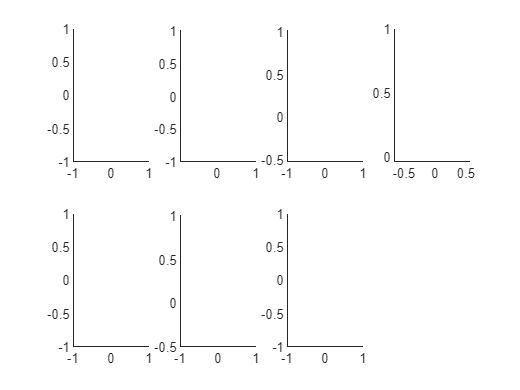

figure(13)
grid on
hold on

for k = 1:(length(uniqueTarget))
    subplot(2,4,k)
    sz = 3;
    ind1 = target ==uniqueTarget(k);
    scatter(dir1(ind1),dir2(ind1), sz, cell2mat(colors(k)), 'filled');
end


%%class 1 and class 2 very overrepresented
%%non-linearity apparentD_mat

D_y = squareform(pdist(Y))

D_y =          0    0.9318    0.9921    0.5549    1.2765    0.5943    0.4641    1.3403    1.0718    1.2832    0.3266    1.3574    0.5554    1.2251    0.3987    1.0444    0.7582    0.6036    0.3438    1.0641    0.3730    1.4020    0.5559    1.1653    1.1020    1.2277    0.8866    0.9893    0.3404    0.9211    0.6508    1.3198    1.2904    1.3666    1.0095    1.2620    1.0943    0.4923    1.2647    0.7462    0.6104    1.0462    1.0565    1.3802    0.9568    1.0434    0.3113    1.0730    0.5757    0.2739
    0.9318         0    0.5980    0.9951    0.7684    1.0879    1.2059    0.9885    0.5835    0.6877    1.0563    0.9954    1.1698    1.0482    1.2107    0.3919    0.8811    0.9595    1.0607    0.9918    1.1730    0.9511    1.2890    0.8493    0.8320    0.9658    1.0049    0.9101    1.1739    0.9808    0.9691    0.8965    0.8297    1.0758    0.9831    0.9939    1.0301    0.7244    0.7186    0.9307    1.1834    0.9923    0.7052    1.0123    0.8679    0.3754    0.9964    0.5854    0.8904   

kruskal = norm(D_mat - D_y, "fro")/norm(D_mat,"fro");

krusk_trunc = 0.3147

%%ISOMAP

rand_index2 = randi(20000,5000,1);
cov_half = cov_normal(rand_index2,:);
target2 = target(rand_index2,:);
D = L2_distance(cov_half', cov_half',1);

[Y, R, E] = IsomapII(D, 'k', 5);

clf
Y_full = Y.coords{3}';
Y1 = Y_full(:,1);
Y2 = Y_full(:,2);
Y3 = Y_full(:,3);

figure(15)
xlabel('ISO1'); ylabel('ISO2'); zlabel('ISO3');
grid on
hold on 
view([162.8 54.0])
for k = 1:length(uniqueTarget)
      ind = target2 == uniqueTarget(k); 
      plot3(Y1(ind),Y2(ind), Y3(ind), '.', 'color', cell2mat(colors(k)), 'markersize',2); 

end

figure(16)
grid on
hold on

for k = 1:(length(uniqueTarget))
    subplot(2,4,k)
    sz = 3;
    ind1 = target2 ==uniqueTarget(k);
    scatter(Y1(ind1),Y2(ind1), sz, cell2mat(colors(k)), 'filled');
end